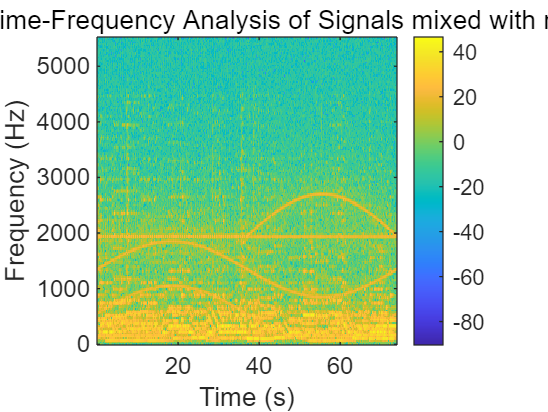

clear all;

Sin = load('Hw2e.mat'); 
load('Sn_ref_d1.mat');

fs = Sin.fs;
sin_frame_e = Sin.Sin_e;     
sn_ref_e = sn_ref_matirx;  
sin_e = sin_frame_e(:, 1);         
sn_ref_e1 = sn_ref_e(:, 1);   
sn_ref_e2 = sn_ref_e(:, 2);   

%RLS
K_order = 10;     
mu = 0.9;     
num_samples = length(sin_e);  

lambda = 0.999; % 遗忘因子
delta = 1e-6;                
W = zeros(K_order, 1);% 滤波器权重
R = delta * eye(K_order);


s_est_e = zeros(num_samples, 1);

for k = 1:num_samples
    sn_ref_frame = sn_ref_e(:, k);  

    %增益向量
    K = (R * sn_ref_frame) / (lambda + sn_ref_frame' * R * sn_ref_frame);
    %误差信号
    ERROR = sin_e(k) - W' * sn_ref_frame;

    W = W + K * ERROR;%更新权重
    R = (1 / lambda) * (R - K * sn_ref_frame' * R); % 更新协方差矩阵

    %估计信号
    s_est_e(k) = ERROR;  
end

N = 400;%窗口
L = N / 2;  
window = hamming(N); 

figure;
[S1, F1, T1] = spectrogram(sin_e, window, L, N, fs);
imagesc(T1, F1, 20 * log10(abs(S1)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Point e: Time-Frequency Analysis of Signals mixed with noise');
colorbar;

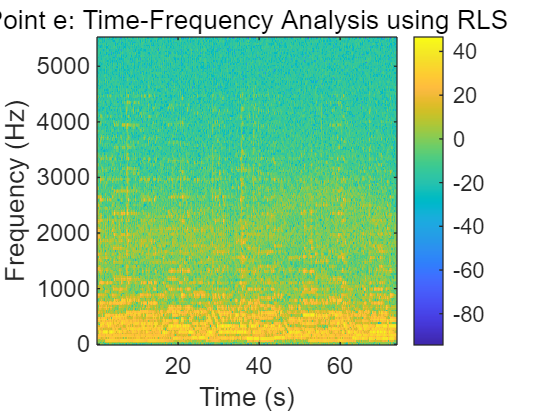


figure;
[S2, F2, T2] = spectrogram(s_est_e, window, L, N, fs);
imagesc(T2, F2, 20 * log10(abs(S2)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Point e: Time-Frequency Analysis using RLS');
colorbar;



% ====== 确保图像刷新后再播放 ======
% drawnow;
pause(0.2);  % 保证图像完全渲染
sound(s_est_e, fs);